clear
clc


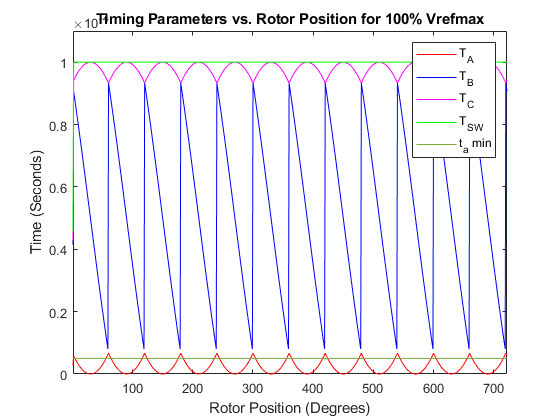

Vdc = 600;                      % Voltage of DC Rail
fsw = 10e3;                     % Switching frequency
Tsw = 1/fsw;                    % Switching period
t_zero_min = 0.05*Tsw;          % Min time of zero switches T7 and T8
Vref_max = (1/sqrt(3))*Vdc;     % Maximum Voltage Amplitude for smooth Vref (346.4 V)
Vref = 1*Vref_max;            % Selected Vref(277.12 V)
ratio = abs(Vref)/((2/3)*Vdc);  % Ratio of Vref to Vdc
x = 1;                          % Initializing variables


%% For loop running through two full rotor rotations. Tsw is assumed as time to move rotor one degree of rotation

for t = 0 :Tsw: 0.072
    x = x + 1;                                                            % Variable iteration
    alpha(x) = x;                                                         % For simplicity, assuming 1 degree of rotor rotation per Tsw
    sector = ceil(mod(alpha(x),360)/60);                                  % Sector calculation that accounts for >360 degrees rotation   
    [Van(x), Vbn(x), Vcn(x), T_A(x), T_B(x), T_C(x), T_SW(x)] = SVM_Timing_and_Vph(sector,Vdc,Tsw,alpha(x),ratio);   % Function call to output phase voltages
end

%% Code for plots

figure(1)

plot(alpha, T_A, 'red', alpha, T_B, 'blue', alpha, T_C, 'magenta', alpha, T_SW, 'green', alpha, (t_zero_min*ones(size(alpha))))
title('Timing Parameters vs. Rotor Position for 100% Vrefmax');
xlabel('Rotor Position (Degrees)');
ylabel('Time (Seconds)');
legend('T_A', 'T_B', 'T_C', 'T_S_W', 't_a min');
xlim(size(alpha));
ylim([0 1.1e-4]);

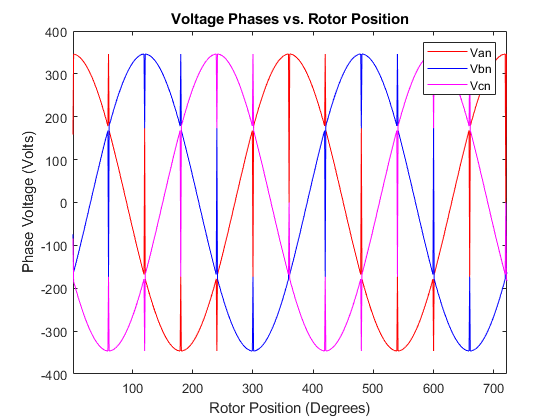


figure(2)

plot(alpha, Van, 'red', alpha, Vbn, 'blue', alpha, Vcn, 'magenta')
title('Voltage Phases vs. Rotor Position');
xlabel('Rotor Position (Degrees)');
ylabel('Phase Voltage (Volts)');
legend('Van', 'Vbn', 'Vcn');
xlim(size(alpha));